# MATLAB Deep Learning Toolbox

## MATLAB Deep Learning Toolbox

To use MATLAB's neural network software, we need to download the [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html#net). The documentation for the shallow neural network can be found on [this page](https://www.mathworks.com/help/deeplearning/getting-started-with-deep-learning-toolbox.html), and there is a really cool GUI tool that covers each step of the training process (which can be called using `nnstart,` and the documentation can found [here](https://www.mathworks.com/help/deeplearning/ref/nnstart.html)). However, we will go over training the same neural network we've trained in the last lecture using the command-line functions.

### Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset we've been using for the last two lectures. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; 
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

### Setting the shallow neural network architecture

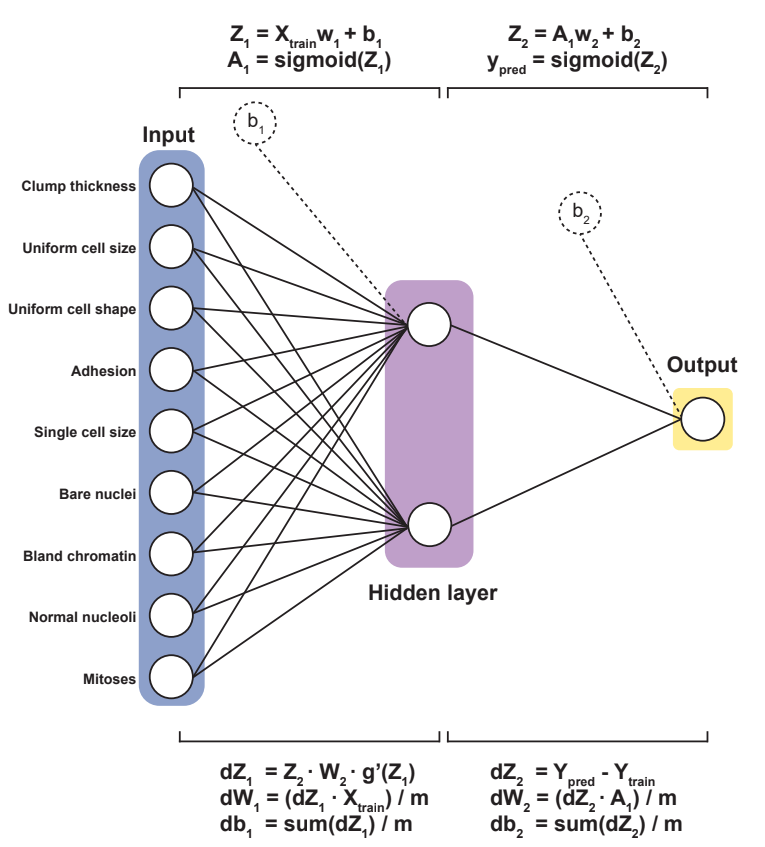

This can be done using the `feedforwardnet` function, which returns a structure consisting of the network values as fields. This function can be used for 1 or more hidden layers. To add more than 1 hidden layer, a vector of values representing the number of activation nodes in each layer can be supplied to construct the network.

Note that as a default, MATLAB uses the** Levenberg-Marquardt** algorithm, another optimization algorithm that tunes the model parameters to minimize the cost function. If you wanted to specify the optimization function as the gradient descent optimization algorithm, you can do so as the second argument in the `feedforwardnet` function. 

numOfActivationNodes = 10;        % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = patternnet(numOfActivationNodes, optimizationFnc)

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

### View the network structure with MATLAB's GUI

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. 

view(net)

The popup screen should show you the following information:

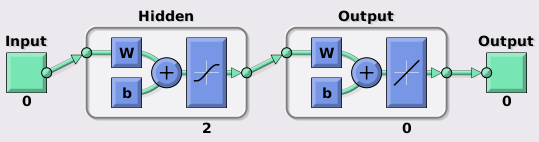

The numbers beneath each panel denotes the number of features (for the input/output) or the number of nodes in the network. Because we have not fitted the data using a training or testing set, the numbers below the input/output in the figure above are shown as 0. 

Note that this diagram is similar to the one we've been using to depict the network structure:

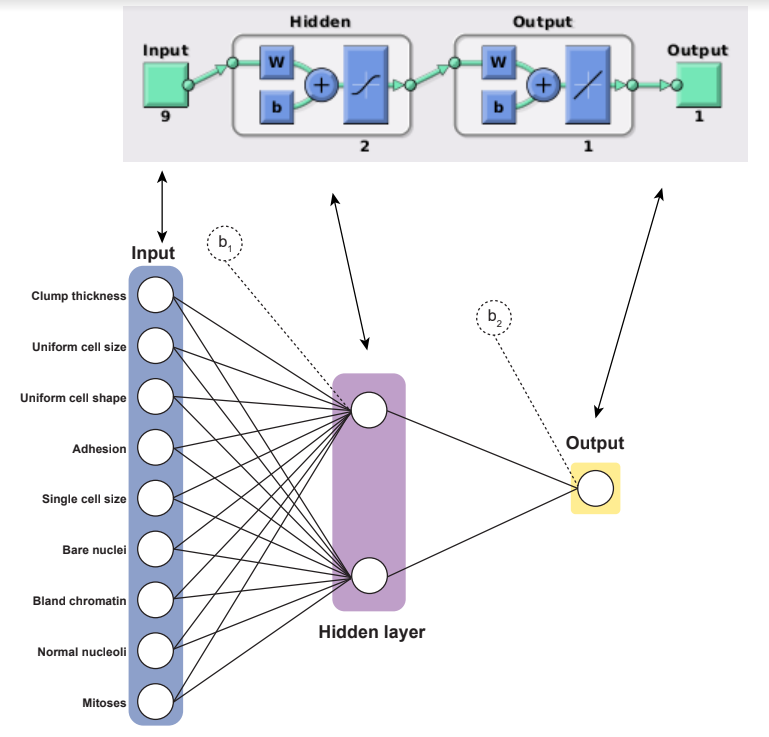

One main difference between the algorithm we wrote and MATLAB's algorithm is that MATLAB only performs a final linear combination from the hidden to the output layer, while we have been re-transforming the linear combination to probabilities using another `Sigmoid` activation function. 

### Setting up the network hyperparameters

Most of the hyperparameters can be modified by setting the fields in the `net` structure. We won't go over each individual hyperparameter here (the documentation to modify some training parameters can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/traingda.html)), but we'll some of the relevant ones we discussed in the previous lectures.

#### Validation sets

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.7; % Training set size
net.divideParam.testRatio  = 0.2; % Test set size
net.divideParam.valRatio   = 0.1; % Cross validation set size

During the training phase, if you input the entire dataset, it automatically splits the dataset into three groups: 60% training, 20% testing (holdout), and an additional 20% for cross validation accuracy determinination. 

#### Loss functions

By default, the loss function is specified as the mean squared error. We'll use the MATLAB default argument, but if we wanted to compute classification errors using the cross entropy loss function, we need to specify the `crossentropy` function using the following syntax:

#### Epochs

The number of epochs can be specified by setting the `net.trainParam.epochs` parameter. While MATLAB performs 1000 epochs by default, we'll set it to 10,000 epochs just to ensure we'll fully train the model. 

net.trainParam.epochs      = 5000;

Note that MATLAB automatically performs **early stopping - **it stops training the model when the model error increases during an epoch. This is a nice feature to implement that helps the model avoid overfitting. 

### Training the shallow neural network

Let's now train the shallow neural network using the `train` function, which will also show the MATLAB GUI while the model is training. An example of the GUI is shown below.

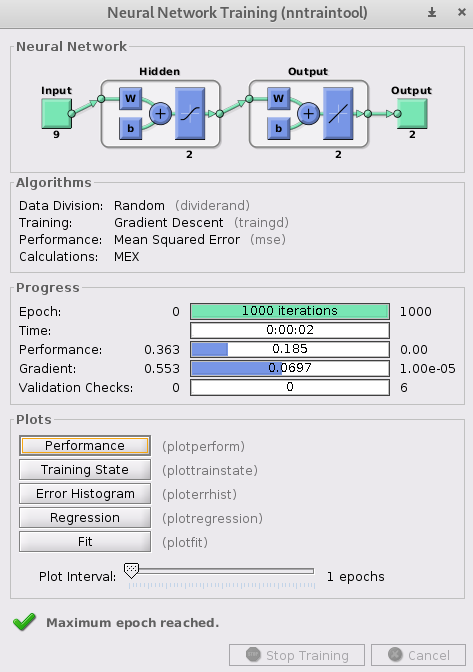

`train` takes in the network architecture we specified (`net)`, the `input` data, and the target labels `outputs`, and outputs the trained neural network (`trainedNet)`, as well as the computed metrics (`trainingRecord)`. 

net.trainParam.showWindow  = 1; 
[trainedNet, trainingRecord] = train(net, X, Y);

### Computing model predictions and evaluating model performance

First, we'll compute our predictions using the test dataset. The trained neural network `trainedNet` also acts as function to compute predictions. We can use the following syntax to compute the predicted Y values from the test set.

ypred = trainedNet(X)

ypred =     0.9862    0.9867    0.9785    0.0389    0.9351    0.9777    0.0035    0.0289    0.0047    0.9827    0.9797    0.0432    0.9826    0.9852    0.3542    0.9376    0.9436    0.9854    0.9876    0.9869    0.0020    0.0216    0.9875    0.9854    0.0133    0.9757    0.9853    0.9850    0.1866    0.2050    0.9641    0.9869    0.0643    0.3806    0.9797    0.9321    0.9790    0.0039    0.9858    0.9875    0.0148    0.9797    0.9869    0.9785    0.0196    0.9881    0.9819    0.0105    0.0072    0.9869
    0.0138    0.0133    0.0215    0.9611    0.0649    0.0223    0.9965    0.9711    0.9953    0.0173    0.0203    0.9568    0.0174    0.0148    0.6458    0.0624    0.0564    0.0146    0.0124    0.0131    0.9980    0.9784    0.0125    0.0146    0.9867    0.0243    0.0147    0.0150    0.8134    0.7950    0.0359    0.0131    0.9357    0.6194    0.0203    0.0679    0.0210    0.9961    0.0142    0.0125    0.9852    0.0203    0.0131    0.0215    0.9804    0.0119    0.0181    0.9895    0.9928 

From here we can use the methods we described previously to evaluate the model. To evaluate the model's performance (mean-squared error), we can use the built-in `perform` function, which has the following syntax:

error = perform(trainedNet, Y, ypred)

error = 0.0581

### Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

figure;
plotperf(trainingRecord)

#### Confusion matrix

To evaluate the average and individual class accuracies, we can use a confusion matrix.

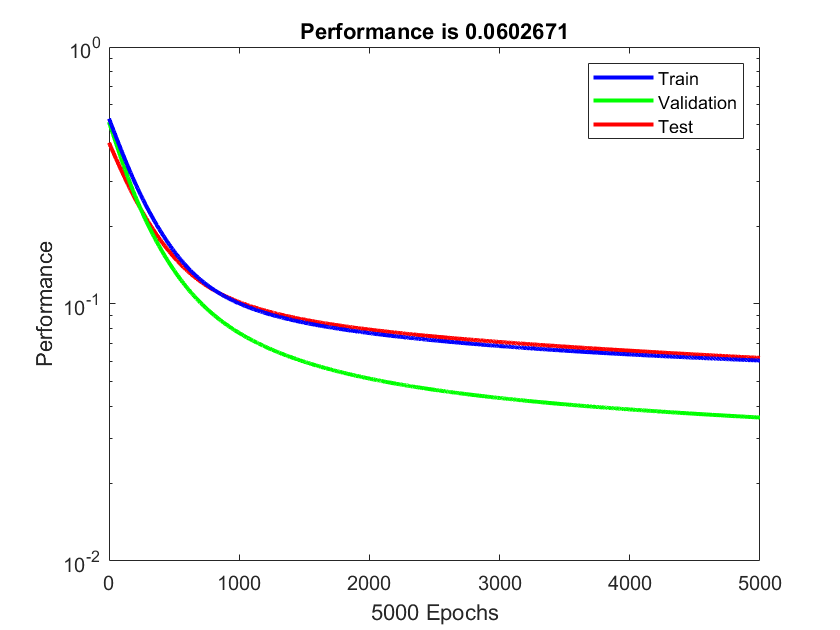

figure;
plotconfusion(ypred, Y);

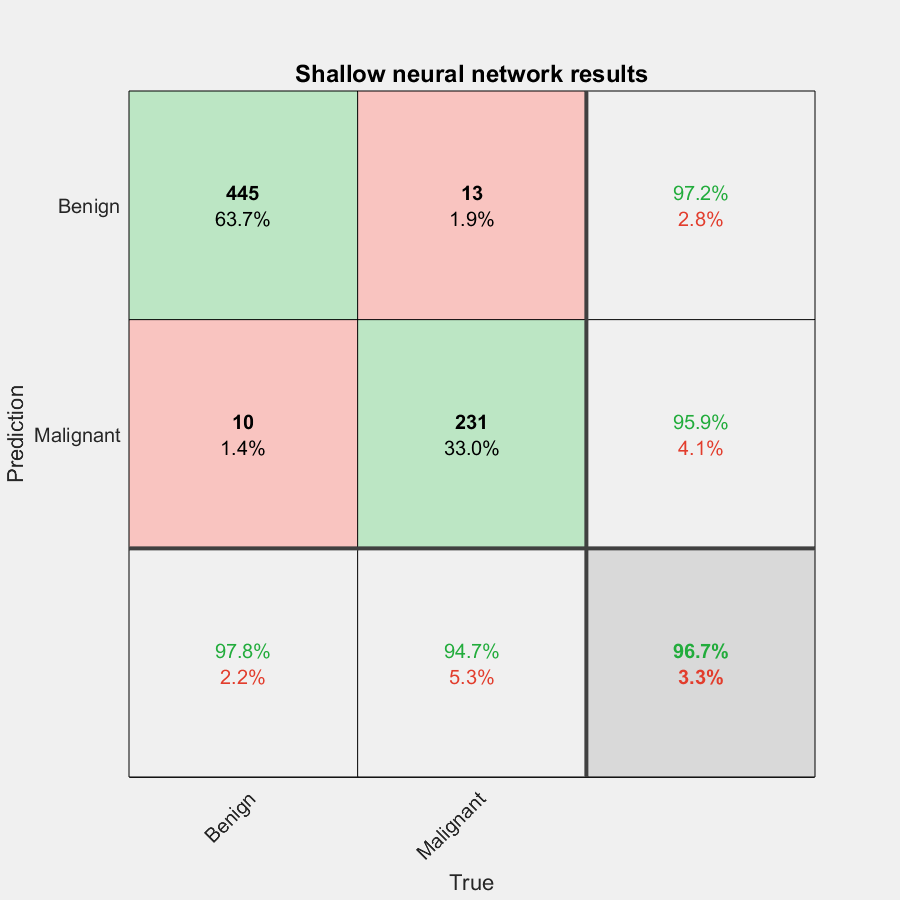

title("Shallow neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

### Hyperparameter tuning

Note that we selected 10 nodes in the hidden layer as an arbitrary example. Is this the best network configuration?

We can perform hyperparameter tuning to find out the answer. Specifically, we will choose the model architecture that has the minimum error if we sample from 2 to 20 nodes.

numOfActivationNodes = [2:20];
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
error                = [];
models               = {};
performance          = {};

for i = 1:length(numOfActivationNodes)
    % Set params
    net                        = patternnet(numOfActivationNodes(i), optimizationFnc);
    net.divideParam.trainRatio = 0.7; % Training set size
    net.divideParam.testRatio  = 0.2; % Test set size
    net.divideParam.valRatio   = 0.1; % Cross validation set size
    net.trainParam.epochs      = 5000;
    net.trainParam.showWindow  = 0;   % Hide UI
    
    % Train network and make prediction
    [trainedNet, trainingRecord] = train(net, X, Y);
    ypred                        = trainedNet(X);
    
    % Cache everything
    error(i)       = perform(trainedNet, Y, ypred);
    models{i}      = trainedNet;
    performance{i} = trainingRecord;
end

Now let's plot the errors

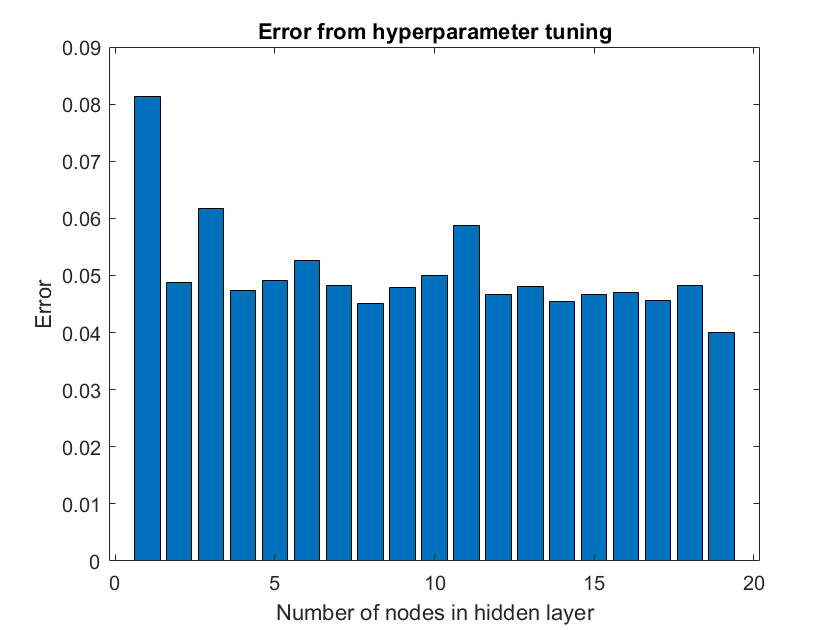

figure;
h = bar(error);
title("Error from hyperparameter tuning");
xlabel("Number of nodes in hidden layer");
ylabel("Error");

## Deep feed-forward neural networks and deep learning

Up until this point, we have only been dealing with a single hidden layer:

What if we wanted to extend our neural network's capacity to handle $L$hidden layers to train a more non-linear model? We can generalize the approach we have used to construct the shallow neural network using the generalized forward and backward propagation algorithm, shown below. 

#### The general forward propagation algorithm

$Z^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L-1\right\rbrack } w^{\left\lbrack L\right\rbrack } +{b\;}^{\left\lbrack L\right\rbrack }$. Note that $A^{\left\lbrack 1\right\rbrack } =X$.

$A^{\left\lbrack L\right\rbrack } =g^{\left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where $g^{\left\lbrack L\right\rbrack }$ is a non-linear function of our choosing at an $L^{\textrm{th}}$ layer.

#### The general backward propagation algorithm

${\textrm{dZ}}^{\left\lbrack L\right\rbrack } ={\textrm{dA}}^{\left\lbrack L\right\rbrack } \cdot$$g^{\prime \left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where ${\textrm{dA}}^{\left\lbrack \textrm{end}\right\rbrack } =Y_{\textrm{train}} -Y_{\textrm{pred}}$ and $g^{\prime \left\lbrack L\right\rbrack }$ is the derivative term for the activation function at layer $L$.


$${\textrm{dA}}^{\left\lbrack L-1\right\rbrack } =W^{\left\lbrack L\right\rbrack } {\textrm{dZ}}^{\left\lbrack L\right\rbrack }$$



$${\textrm{dW}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({{\textrm{dZ}}^{\left\lbrack L\right\rbrack } A}^{\left\lbrack L-1\right\rbrack } \right);$$

$${\textrm{db}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({\textrm{dZ}}^{\left\lbrack L\right\rbrack } \right)$$


### Deep neural networks from the Deep Learning Toolbox

MATLAB has made it easy to construct deep neural networks by simply using the `trainNetwork` function. It takes in the datasets $X_{\textrm{train}}$ and $Y_{\textrm{train}}$, the network architecture as the third argument, and the hyperparameter specifications in the 4th argument. We'll use the breast cancer imaging dataset to train and test this deep neural network.

clear all; rng(2);
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xval, Yval] = ...
    trainTestSplit(X', Y', ...
    trainingSize, randomstate);

% Re-format so the DLT can use the data
Xtrain = Xtrain';              Xval = Xval';
Ytrain = categorical(Ytrain'); Yval = categorical(Yval');

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. We'll be constructing a deep neural network that has the following structure:

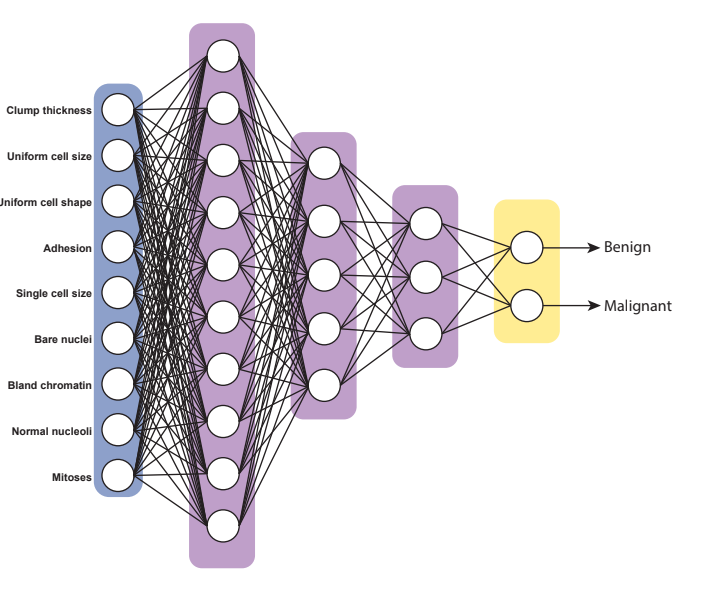

**There are 4 components we need to specify in the **`layer`** array:**

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(X, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 1
    
    fullyConnectedLayer(5, ...                         % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 2
    
    fullyConnectedLayer(3, ...                         % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 3
    
    fullyConnectedLayer(2, ...                          % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Transform to probabilities
    
    classificationLayer ...                             % Label encode
]

layers =   10x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 9 dimensions
     2   ''   Fully Connected         10 fully connected layer
     3   ''   Softmax                 softmax
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Fully Connected         3 fully connected layer
     7   ''   Softmax                 softmax
     8   ''   Fully Connected         2 fully connected layer
     9   ''   Softmax                 softmax
    10   ''   Classification Output   crossentropyex

analyzeNetwork(layers)

Next, we have to specify the model hyperparameters. The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 200, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xval, Yval(1, :)}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);                

Finally, let's train the neural network using the `trainNetwork` function, which allows us to train other deep neural network architectures. 

For more information on other neural networks you can train using this function, you can [read the documentation](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html).

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:00 |       33.45% |       61.43% |       0.6974 |       0.6915 |          0.0100 |


|      30 |          30 |       00:00:00 |       66.55% |       61.43% |       0.6385 |       0.6794 |          0.0100 |


|      50 |          50 |       00:00:01 |       66.55% |              |       0.6371 |              |          0.0100 |


|      60 |          60 |       00:00:01 |       66.55% |       61.43% |       0.6354 |       0.6691 |          0.0100 |


|      90 |          90 |       00:00:01 |       66.55% |       61.43% |       0.4939 |       0.5116 |          0.0100 |


|     100 |         100 |       00:00:01 |       95.71% |              |       0.3900 |              |          0.0100 |


|     120 |         120 |       00:00:01 |       97.50% |       97.14% |       0.2321 |       0.2342 |          0.0100 |


|     150 |         150 |       00:00:02 |       97.67% |       96.43% |       0.1412 |       0.1454 |          0.0100 |


|     180 |         180 |       00:00:02 |       97.85% |       97.14% |       0.1126 |       0.1199 |          0.0100 |


|     200 |         200 |       00:00:02 |       98.03% |       97.14% |       0.1030 |       0.1122 |          0.0100 |


|======================================================================================================================|


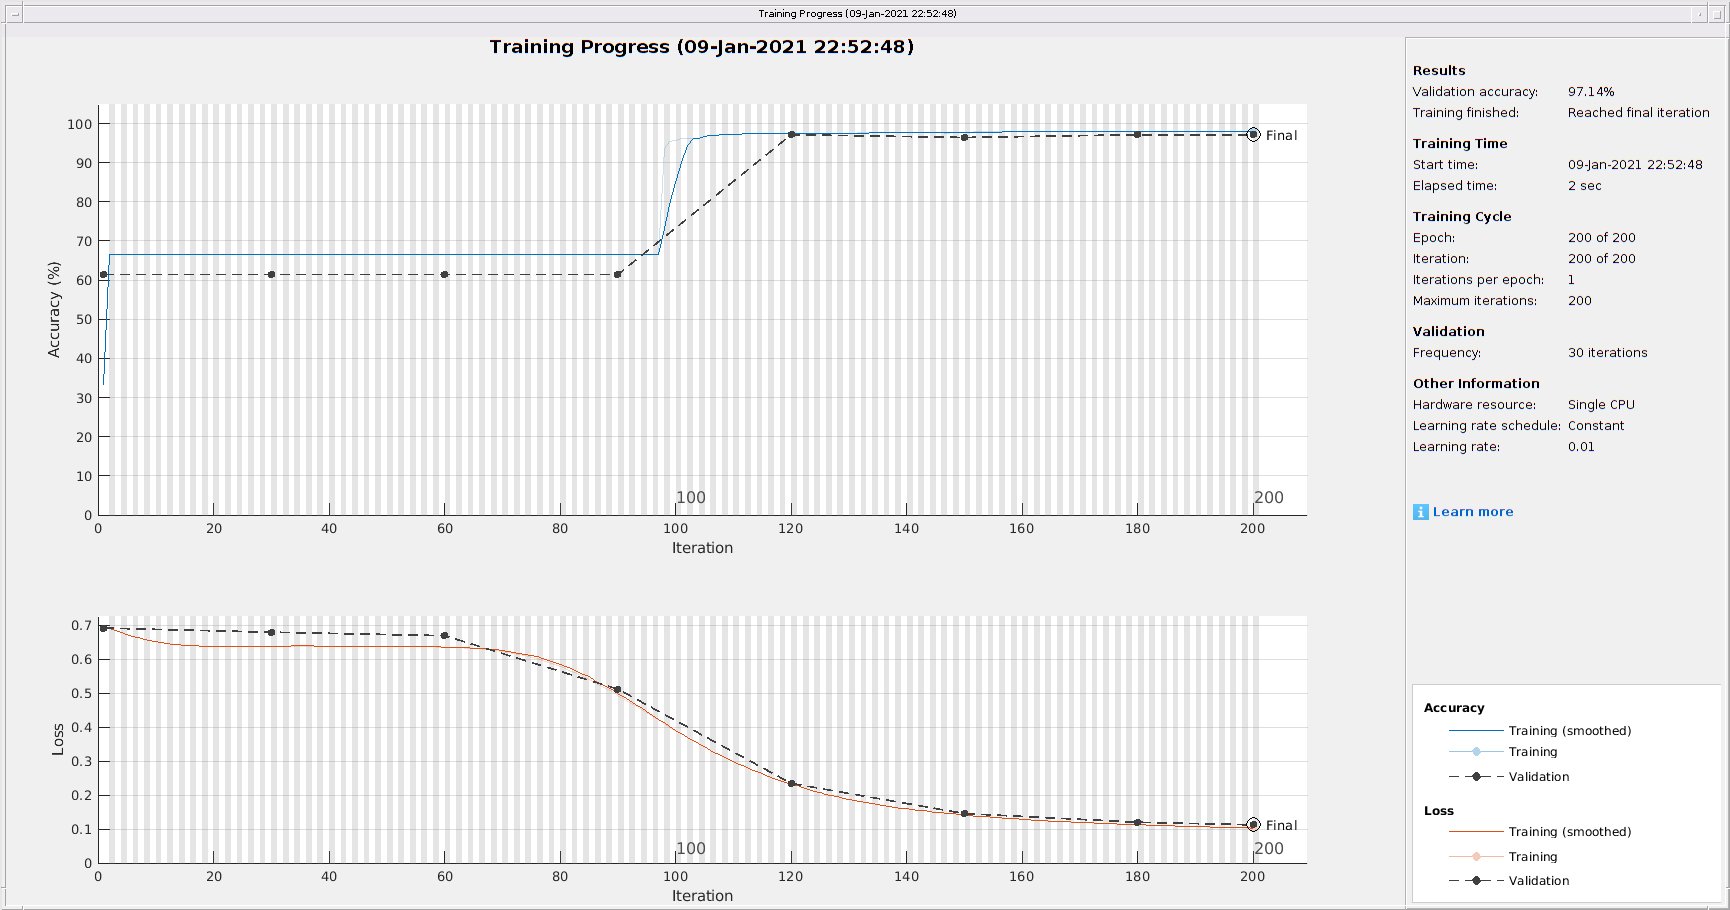

dnn =   SeriesNetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


trainingInfo = struct with fields:
               TrainingLoss: [1×200 double]
           TrainingAccuracy: [1×200 double]
             ValidationLoss: [1×200 double]
         ValidationAccuracy: [1×200 double]
              BaseLearnRate: [1×200 double]
        FinalValidationLoss: 0.1122
    FinalValidationAccuracy: 97.1429


[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain(1, :), layers, options)

The plot shown in the popup shows the accuracy and cost of training the neural network as a function the number of epochs, and shows the generation of the accuracy / cost curves in real time. 

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_dnn = classify(dnn, Xval)

ypred_dnn = 1×140 categorical array
     0      0      1      0      1      1      0      0      1      1      0      0      1      0      0      1      1      0      0      1      0      0      0      1      1      1      0      1      0      0      0      1      0      1      1      0      0      1      1      1      0      1      1      1      1      1      1      0      1      0      1      1      1      1      0      1      1      0      1      1      1      1      0      1      0      0      1      1      1      1      0      0      0      1      1      0      0      1      0      1      1      0      1      0      0      0      0      1      0      1      1      1      1      1      1      1      1      0      1      0      1      1      1      1      1      1      1      0      1      1      1      1      0      1      0      0      0      1      0      0      1      1      1      0      1      1      0      1      1      1      1      1      1      0      0      0      1      

### Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

#### Confusion matrix

To evaluate the average and individual class accuracies, we can use a confusion matrix.

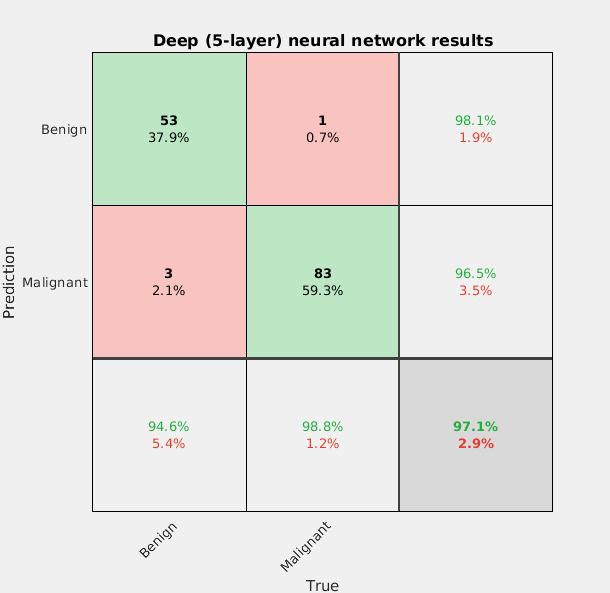

figure;
plotconfusion(ypred_dnn, Yval(1, :));
title("Deep (5-layer) neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

## Summary

We've learned MATLAB's functions for training neural networks, and applied them to k-class classification problems. Finally, we covered how to use MATLAB's deep neural network toolbox to train a deep neural network. An additional lecture (`imaging.mlx)` has been provided to show how deep neural networks can be used in regression problems to analyze tumor imaging data.

In the final part of this lecture series, we'll discuss potential difficulties in training neural networks, strategies to address these potential difficulties, and how to optimize the training phase using parallel computing and hyperparameter optimization. 

### Built-in MATLAB functions

`feedforwardnet:           `Initializes a feedforward neural network structure.

`plotperf:                 `Plots the cost curves from training a neural network.

`train:                    `Trains a shallow / feedforward neural network object.

`classificationLayer:      `Computes the cross entropy loss for multi-class classification problems.

`softmaxLayer:            `  Creates a softmax activation function layer for binary- and multi-classification problems.

`sequenceInputLayer:       `Stores the input dataset $X_{\textrm{train}}$ as a MATLAB object for the `trainNetwork` function.

`fullyConnectedLayer:      `Creates a single hidden layer object for the` trainNetwork `function.

`trainingOptions:          `Creates an object used in the `trainNetwork` function that specifies the neural network hyperparameters.

`trainNetwork:             `Trains (among other network structures) a deep feedforward neural network.

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat.`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$ dataset